Yi Zou 12213036

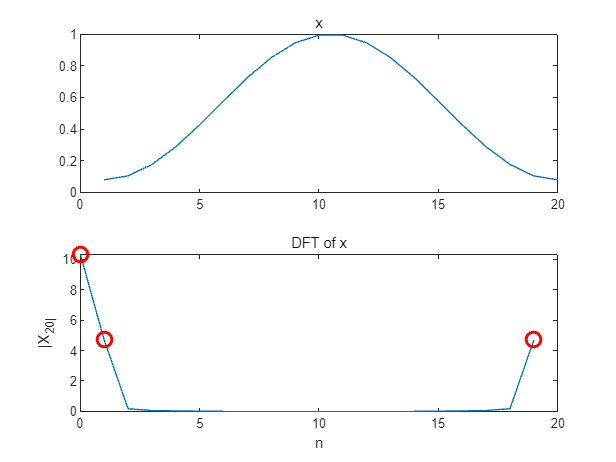

x = hamming(20);
N = length(x);
subplot(211)
plot(x), title("x")
X = DFTsum(x);
subplot(212)
k = 0:19;
plot(k, abs(X)), ylabel("x")
hold on
plot(0, abs(X(1)), 'ro', 'MarkerSize', 10, 'LineWidth', 2)
plot(1, abs(X(2)), 'ro', 'MarkerSize', 10, 'LineWidth', 2)
plot(19, abs(X(end)), 'ro', 'MarkerSize', 10, 'LineWidth', 2)
title("DFT of x"), xlabel("n"), ylabel("|X_20|")
hold off

% [X_,w] = DTFTsample(x,X);
[X_,w] = DTFTsamples(x)

X_ =    0.0000 + 0.0000i
   0.0003 - 0.0020i
   0.0014 - 0.0042i
   0.0033 - 0.0066i
   0.0069 - 0.0094i
   0.0132 - 0.0132i
   0.0256 - 0.0186i
   0.0553 - 0.0282i
   0.1648 - 0.0535i
  -4.6407 + 0.7350i


w =    -3.1416   -2.8274   -2.5133   -2.1991   -1.8850   -1.5708   -1.2566   -0.9425   -0.6283   -0.3142         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274


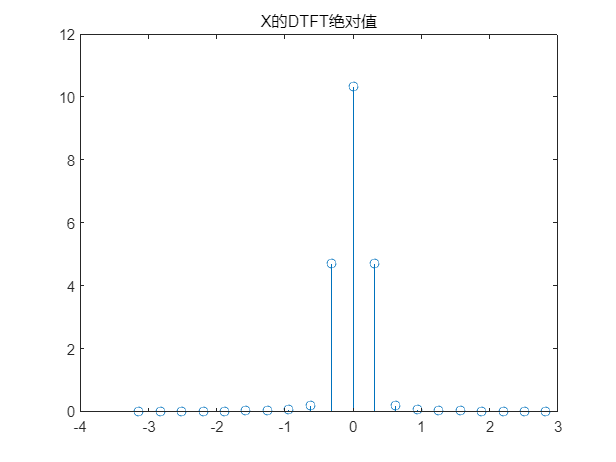

figure
stem(w,abs(X_))
title("X的DTFT绝对值")

5.2.2 Zero Padding

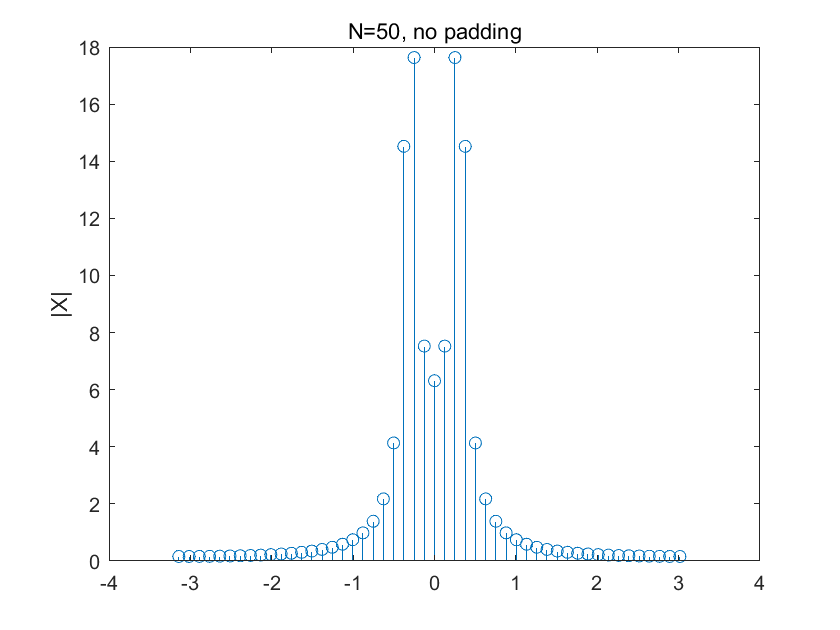

x1=sin(0.1*pi.*(0:49));
x2=[x1, zeros(1,150)];
x3 = sin(0.1*pi.*(0:199));
[X3, w3] = DTFTsamples(x3);
[X1, w1] = DTFTsamples(x1);
[X2, w2] = DTFTsamples(x2);

figure
stem(w1, abs(X1))
title("N=50, no padding"), ylabel("|X|")

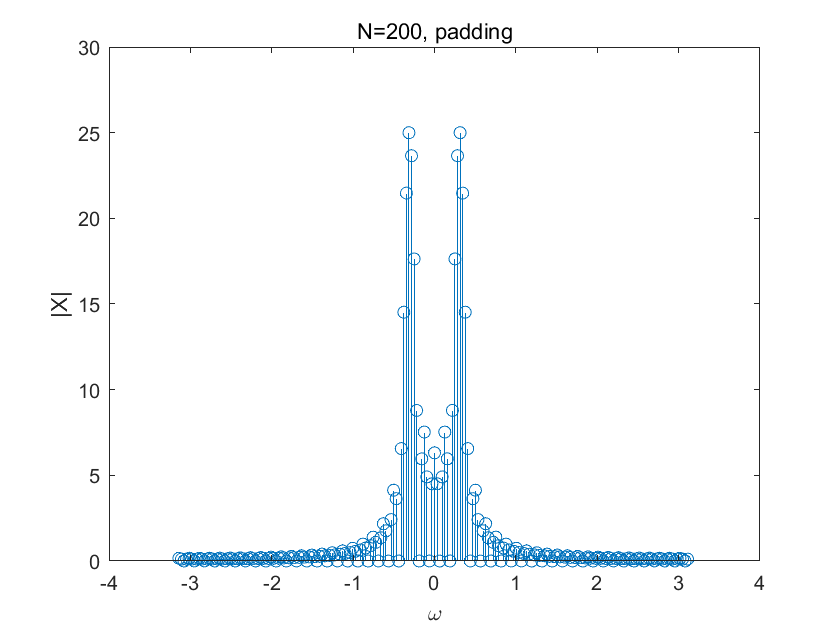



figure
stem(w2, abs(X2))
title("N=200, padding"), ylabel("|X|"), xlabel("\omega")

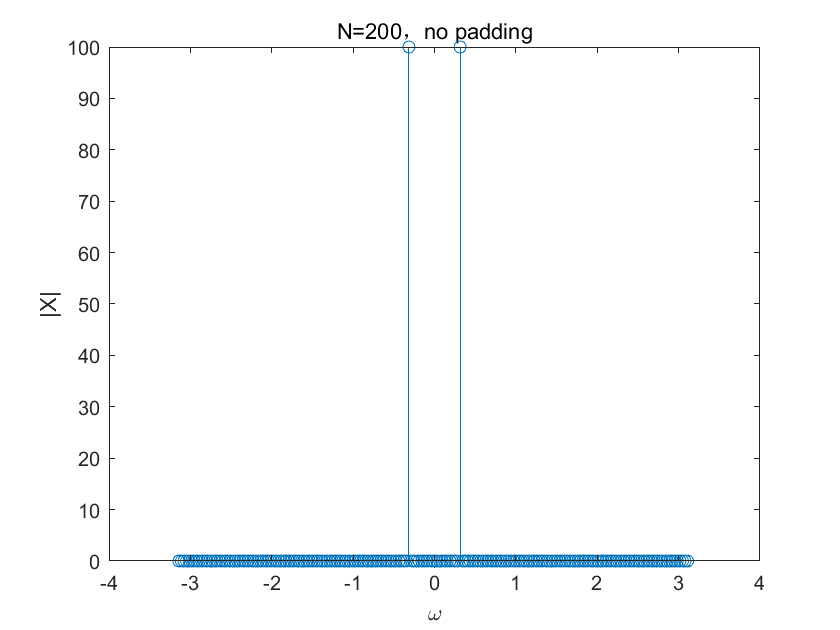


figure
stem(w3, abs(X3))
title("N=200，no padding"), ylabel("|X|"), xlabel("\omega")

N=200 is more like DTFT

The different value of N contributes to the different look of the plots.

5.3.1 FFT

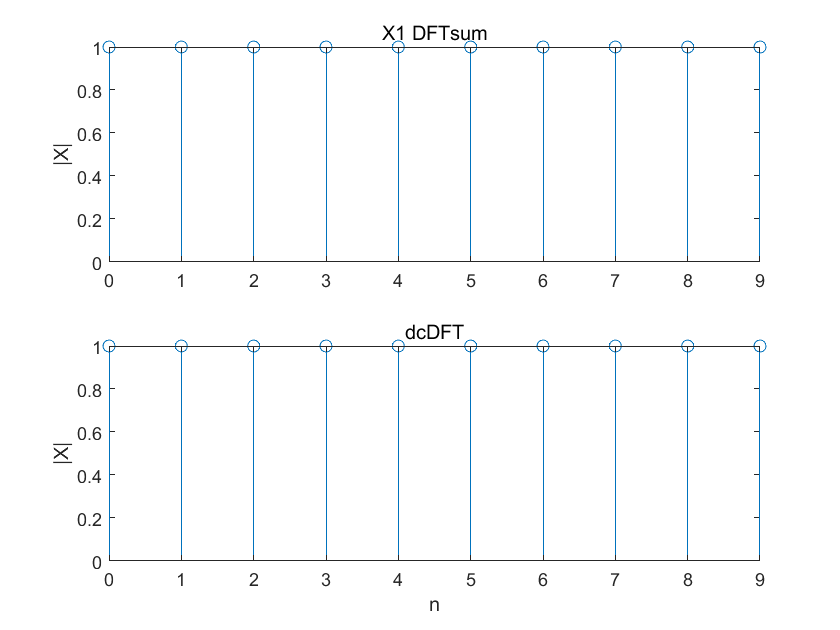

n = 0:9;
x1 = [1, zeros(1, 9)];
N1 = length(x1);
x2 = ones(1, 10);
N2 = length(x2);
x3 = exp(1j*2*pi*n/10);
N3 = length(x3);

figure
subplot(211) 
stem(n, abs(DFTsum(x1)))
title('X1 DFTsum')
ylabel('|X|')

subplot(212)
stem(n, abs(dcDFT(x1)))
title('dcDFT')
ylabel('|X|')
xlabel('n')

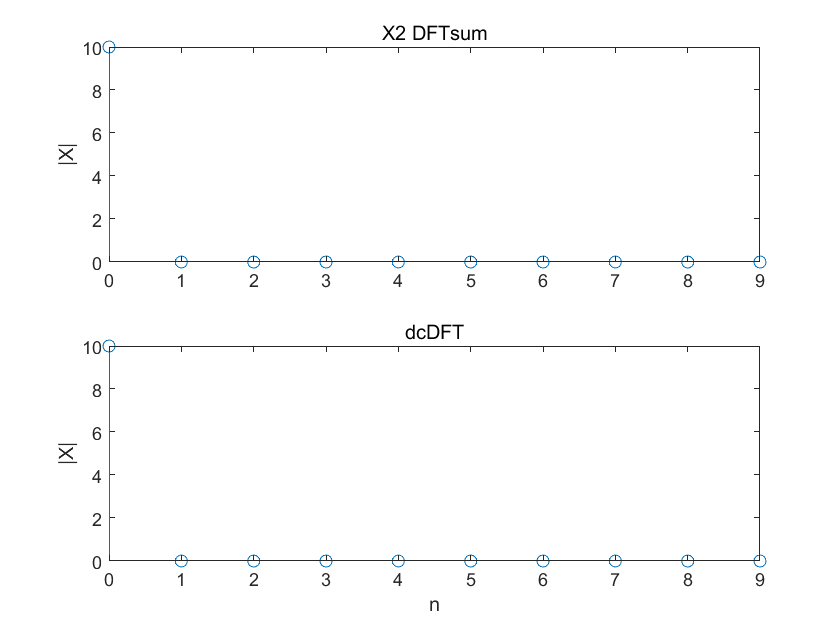


figure
subplot(211)
stem(n, abs(DFTsum(x2)))
title('X2 DFTsum'), ylabel('|X|')
subplot(212)
stem(n, abs(dcDFT(x2)))
title('dcDFT')
ylabel('|X|')
xlabel('n')

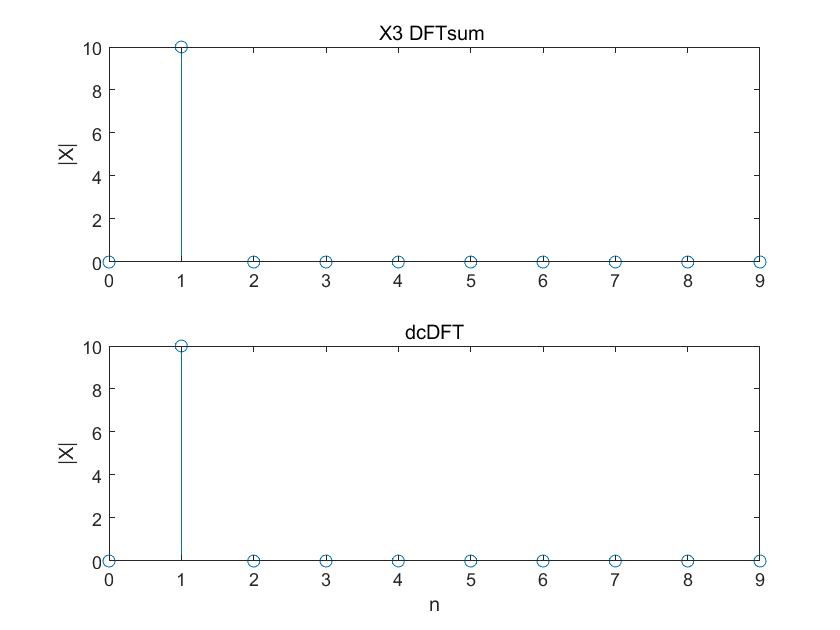


figure
subplot(211) 
stem(n, abs(DFTsum(x3)))
title('X3 DFTsum ')
ylabel('|X|')
subplot(212)
stem(n, abs(dcDFT(x3)))
title('dcDFT')
ylabel('|X|')
xlabel('n')

5.3.2 FFT

n=0:7;
x1 = [1, zeros(1, 7)];
x2 = ones(1, 8);
x3 = exp(1j * 2 * pi * n/8);

figure, subplot(211)
stem(n, abs(DFTsum(x1)))
title('X1 DFTsum'), ylabel('|X|')
subplot(212)
stem(n, abs(FFT8(x1)))

     4

     4

     8



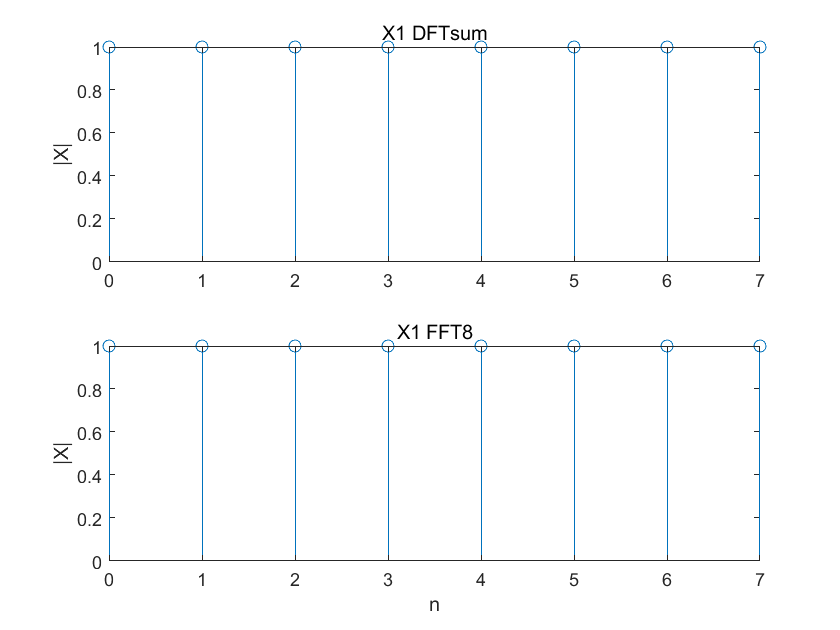

title('X1 FFT8'), ylabel('|X|'), xlabel('n')


figure, subplot(211)
stem(n, abs(DFTsum(x2)))
title('X2 DFTsum'), ylabel('|X|')
subplot(212)
stem(n, abs(FFT8(x2)))

     4

     4

     8



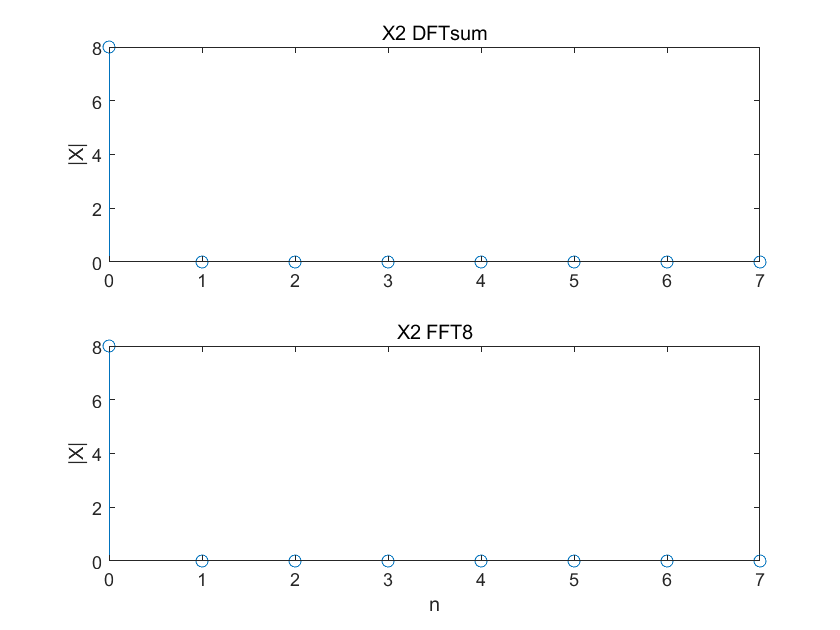

title('X2 FFT8'), ylabel('|X|'), xlabel('n')


figure
subplot(211)
stem(n, abs(DFTsum(x3)))
title('X3 DFTsum'), ylabel('|X|')
subplot(212)
stem(n, abs(FFT8(x3)))

     4

     4

     8



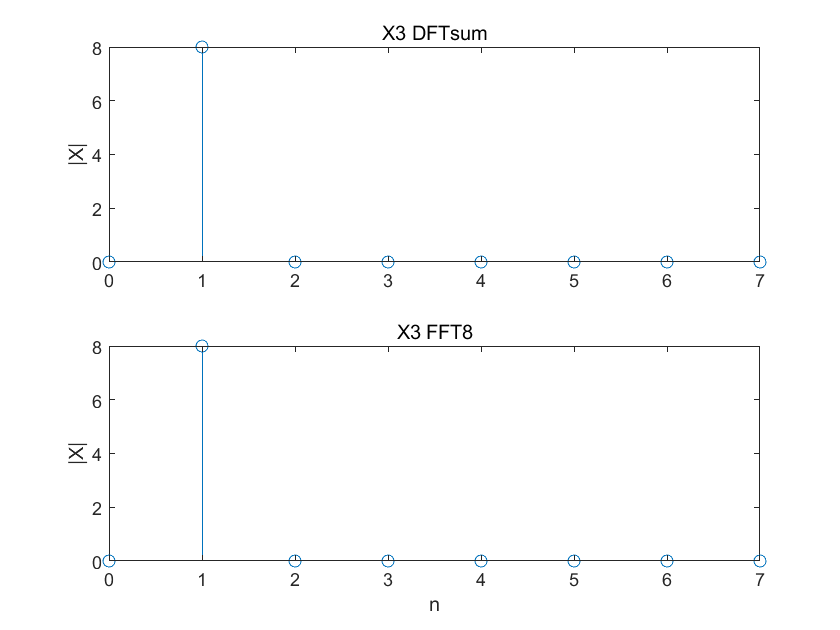

title('X3 FFT8'), ylabel('|X|'), xlabel('n')

function X=DFTsum(x)
    
    N = length(x);
    X = zeros(1, N);

    for k = 0:N-1
        for n = 0:N-1
            X(k+1)=X(k+1) + x(n+1) * exp(-1j*2*pi*k*n/N);
        end
    end
end


% function [X,w] = DTFTsamples(x)
%     N = length(x);
%     k = 0:N-1;
%     w = 2*pi*k/N;
%     w(w>=pi) = w(w>=pi)-2*pi;    %频率范围转变
%     w = fftshift(w);
%     X = fftshift(abs(DFTsum(x,N)))
% end


function [X_,w] = DTFTsample(x,X)
    N = length(x);
    k = 0:N-1;
    w = 2*pi*k/N;
    w(w>=pi) = w(w>=pi) - 2*pi;
    X_ = DFTsum(x,N)
    figure
    stem(fftshift(w), fftshift(abs(X)))
end


function [X, w]=DTFTsamples(x)
    
    N = length(x);
    w = linspace(-pi, pi, N+1);
    w = w(1:end-1);
    X = zeros(N, 1);
    for k = 1:N
        for n = 1:N
            X(k) = X(k)+x(n)*exp(-1j*w(k)*(n-1));
        end
    end
end


% function X = FFT4(x)
%     r = [0,1];
%     X0 = FFT2([x(1) x(3)]);
%     X1 = FFT2([x(2) x(4)]);
%     temp = X1 .* exp
% end


function X = FFT2(x)
    X(1) = x(1)+x(2);
    X(2) = x(1)-x(2);
end


function X = FFT4(x)
    X0 = FFT2(x(1:2:4));
    X1 = FFT2(x(2:2:4));
    W = exp(-1j*2*pi*(0:1)/4);
    X(1:2) = X0 + W .* X1;
    X(3:4) = X0 - W .* X1;
    disp(4)
end


function X = FFT8(x)
    X0 = FFT4(x(1:2:8));
    X1 = FFT4(x(2:2:8));

    W = exp(-1j*2*pi*(0:3)/8);

    X(1:4) = X0 + W .* X1;
    X(5:8) = X0 - W .* X1;
    disp(8)
end

function X = dcDFT(x)
    N = length(x);
    X = zeros(1, N);
    x0 = x(1:2:N);
    x1 = x(2:2:N);
    X0 = DFTsum(x0);
    X1 = DFTsum(x1);
    
    W = exp(-1j*2*pi*(0:N/2-1)/N);

    X(1:N/2) = X0 + W .* X1;
    X(N/2+1:N) = X0 - W .* X1;
end






